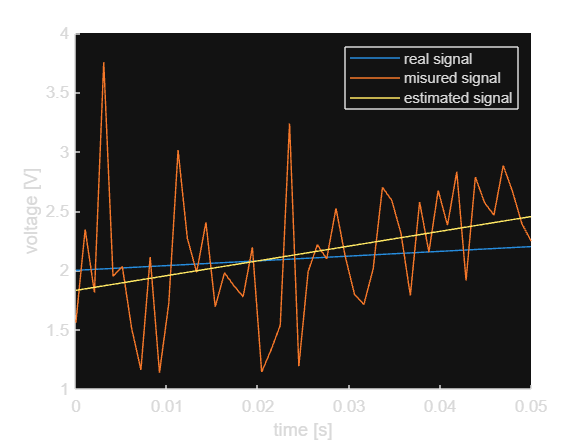

SIZE = 50;
dt = 1e-3;
t = (linspace(0, SIZE, SIZE) * dt)';

theta = [2; 4];

hold on;
x = theta(1) * ones(SIZE, 1) + theta(2) .* t;
y = x + randn(SIZE, 1) * 0.5;
plot(t, x)
plot(t, y)
xlabel('time [s]')
ylabel('voltage [V]')

A = [ones(SIZE, 1), t];
Q = (A'*A)^-1;
C = Q*A';
P = A*C;

theta_hat = C * y;
theta_ = C * x; % should be == theta
x_hat = P * y;
plot(t, x_hat)

legend('real signal', 'misured signal', 'estimated signal')
hold off; clf; clc;

close all force;

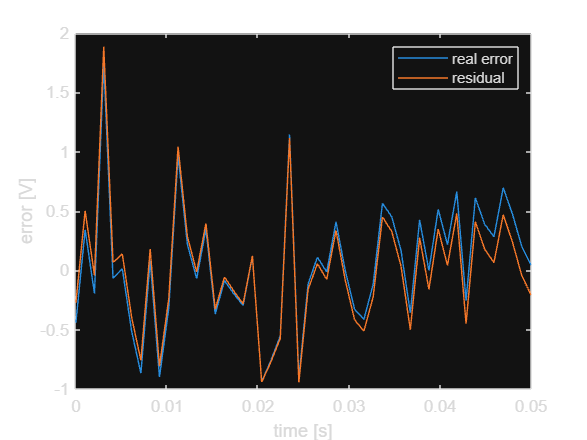

e = y - x;
e_hat = y - x_hat;
plot(t, e)
hold on;
plot(t, e_hat)
xlabel('time [s]')
ylabel('error [V]')
legend('real error', 'residual')


mean_e_hat = mean(e_hat);
var = sum((e_hat - mean_e_hat).^2) / SIZE;
sigma = sqrt(var);

clc;